net = alexnet;
imagePath = 'C:\Users\User\Google Drive\Greenstand\ANCombined';

 imds = imageDatastore(imagePath,'IncludeSubfolders',true,'LabelSource','foldernames');
 [trainIm, testIm] = splitEachLabel(imds, 0.8,'randomized')

trainIm =   ImageDatastore with properties:

                       Files: {
                              'C:\Users\User\Google Drive\Greenstand\ANCombined\BroadLeaf\10.jpg';
                              'C:\Users\User\Google Drive\Greenstand\ANCombined\BroadLeaf\10091.jpg';
                              'C:\Users\User\Google Drive\Greenstand\ANCombined\BroadLeaf\10096.jpg'
                               ... and 555 more
                              }
                      Labels: [BroadLeaf; BroadLeaf; BroadLeaf ... and 555 more categorical]
    AlternateFileSystemRoots: {}
                    ReadSize: 1
                     ReadFcn: @readDatastoreImage


testIm =   ImageDatastore with properties:

                       Files: {
                              'C:\Users\User\Google Drive\Greenstand\ANCombined\BroadLeaf\10097.jpg';
                              'C:\Users\User\Google Drive\Greenstand\ANCombined\BroadLeaf\1015.jpg';
                              'C:\Users\User\Google Drive\Greenstand\ANCombined\BroadLeaf\10687.jpg'
                               ... and 135 more
                              }
                      Labels: [BroadLeaf; BroadLeaf; BroadLeaf ... and 135 more categorical]
    AlternateFileSystemRoots: {}
                    ReadSize: 1
                     ReadFcn: @readDatastoreImage


 
 trainData = augmentedImageDatastore([227 227], trainIm)

trainData =   augmentedImageDatastore with properties:

           MiniBatchSize: 128
         NumObservations: 558
        DataAugmentation: 'none'
      ColorPreprocessing: 'none'
              OutputSize: [227 227]
          OutputSizeMode: 'resize'
    DispatchInBackground: 0


testData = augmentedImageDatastore([227 227], testIm)

testData =   augmentedImageDatastore with properties:

           MiniBatchSize: 128
         NumObservations: 138
        DataAugmentation: 'none'
      ColorPreprocessing: 'none'
              OutputSize: [227 227]
          OutputSizeMode: 'resize'
    DispatchInBackground: 0


layer = net.Layers

layer =   25x1 Layer array with layers:

     1   'data'     Image Input                   227x227x3 images with 'zerocenter' normalization
     2   'conv1'    Convolution                   96 11x11x3 convolutions with stride [4  4] and padding [0  0  0  0]
     3   'relu1'    ReLU                          ReLU
     4   'norm1'    Cross Channel Normalization   cross channel normalization with 5 channels per element
     5   'pool1'    Max Pooling                   3x3 max pooling with stride [2  2] and padding [0  0  0  0]
     6   'conv2'    Convolution                   256 5x5x48 convolutions with stride [1  1] and padding [2  2  2  2]
     7   'relu2'    ReLU                          ReLU
     8   'norm2'    Cross Channel Normalization   cross channel normalization with 5 channels per element
     9   'pool2'    Max Pooling                   3x3 max pooling with stride [2  2] and padding [0  0  0  0]
    1

layer(23) = fullyConnectedLayer(6,'Name','fcfinal');
layer(end) = classificationLayer('Name','myClassification');
            

opts = trainingOptions('adam','InitialLearnRate',0.0001,'Plots','training-progress','MaxEpochs',10);

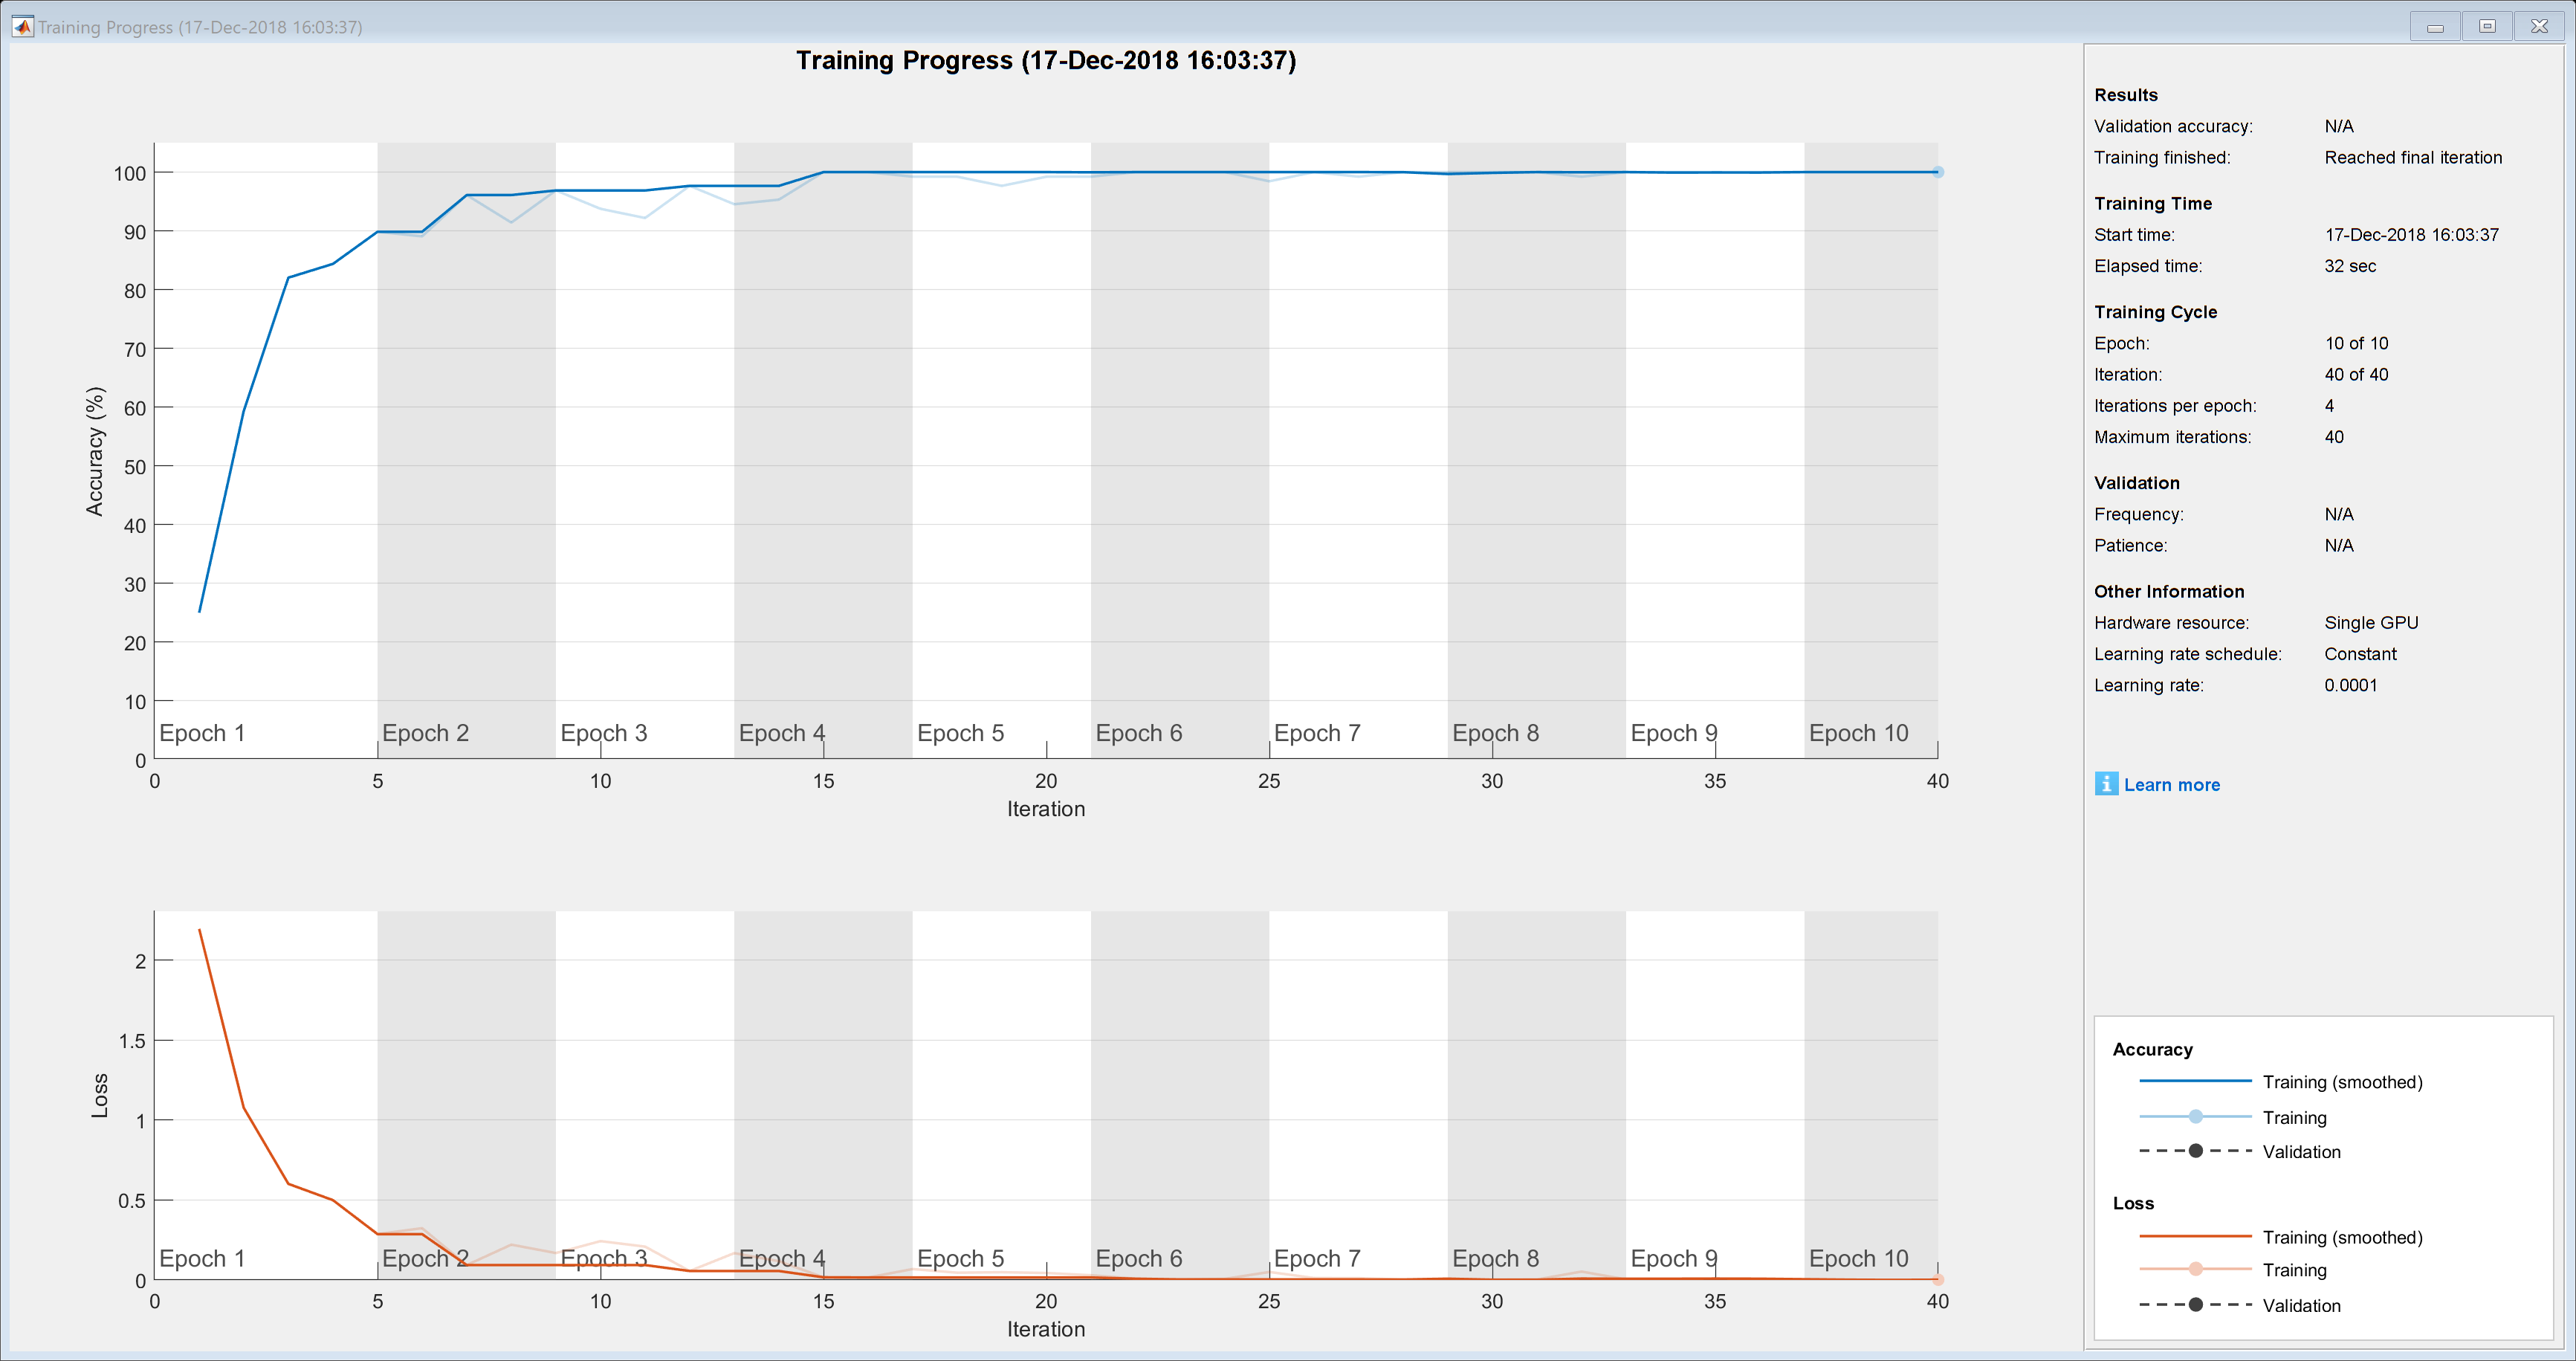

Training on single GPU.


Initializing image normalization.
|========================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Mini-batch  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |     Loss     |      Rate       |
|========================================================================================|
|       1 |           1 |       00:00:02 |       25.00% |       2.1958 |      1.0000e-04 |
|      10 |          40 |       00:00:32 |      100.00% |       0.0013 |      1.0000e-04 |
|========================================================================================|


[net,info] = trainNetwork(trainData,layer,opts);

predLabels = classify(net,testData);
numCorrect = nnz(predLabels==testIm.Labels);
accuracy = numCorrect/numel(predLabels)

accuracy = 0.9348

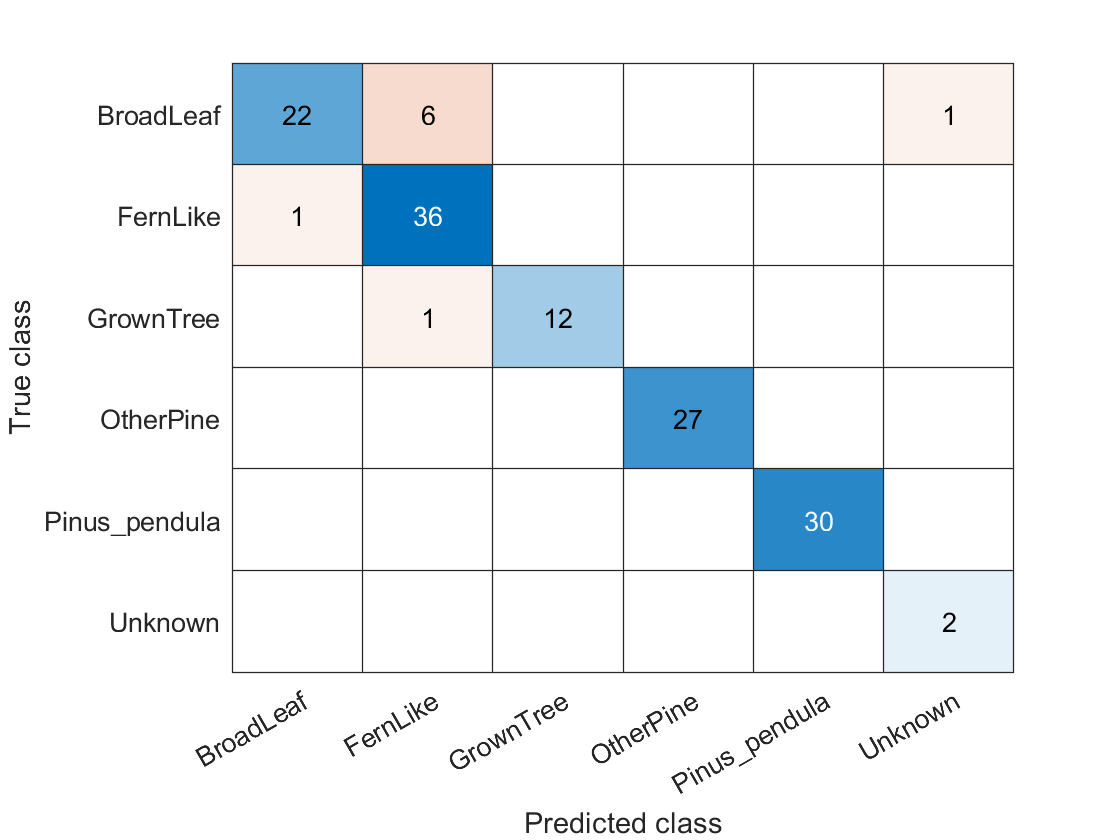

confusionchart(testIm.Labels,predLabels);


cc.ColumnSummary = 'column-normalized';
cc.RowSummary = 'row-normalized';
cc.Title = 'Plant Image Confusion Matrix';